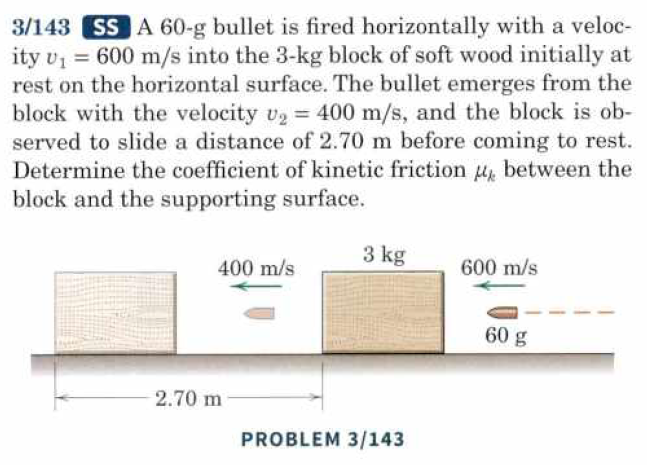

% 3.143
clear

g = 9.81;


% Kuglen
mb = 0.060;    vb1 = 600; vb2 = 400;

% Kassen
mk = 3;    vk2 = 0;    dist = 2.7;

syms vk1
pb1 = mb*vb1;
pb2 = mb*vb2;
pk1 = mk*vk1;
pk2 = mk*vk2;

% Kassens starthastighed
eq = pb1 - pk1 == pb2 - pk2;
vk1 = rhs(isolate(eq, vk1))

$$vk1 = 4$$


% Friktionskoefficienten udledt ud fra energibevarelse
displayFormula("U = Ekin - Egrav = 0")

$$\left(U=\mathrm{Ekin}-\mathrm{Egrav}\right)=0$$


syms mu_k
Ekin = 1/2*mk*(vk2^2 - vk1^2);
Egrav = -mu_k*mk*g*dist;

U = Ekin - Egrav == 0;

mu_k = vpa(solve(U, mu_k),4)

$$mu\_k = 0.302$$

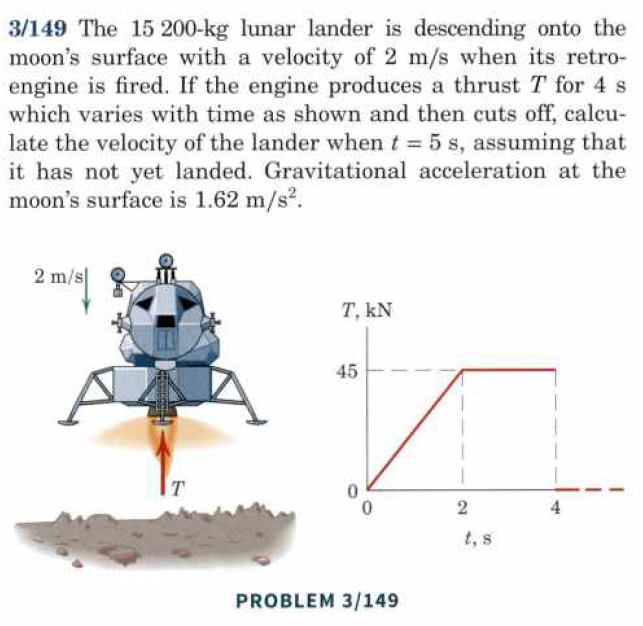

clc
clear
u = symunit;

g = 1.62 * u.m/u.s^2;

% Rumskib data
m = 15200*u.kg; v1 = 2*u.m/u.s; T = 45*u.kN;

t = 5*u.s; t1 = 2*u.s;  t2 = 4*u.s;


v2 = -g*t + (T/2*2*u.s/m + T*2*u.s/m - v1)

$$v2 = \frac{27}{3040}\,\frac{\mathrm{kN}\,s}{\mathrm{kg}}-\frac{101}{10}\,\frac{m}{s}$$

disp("Løst i hånden, svært i matlab med integration")

Løst i hånden, svært i matlab med integration


disp("Hastigheden er i nedadgående retning")

Hastigheden er i nedadgående retning


v2 = vpa(unitConvert(v2, u.m/u.s),4)

$$v2 = -1.218\,\frac{m}{s}$$

clear

g = 1.62;

% Rumskib data
m = 15200; v1 = 2; T = 45000;

ts = 5; t1 = 2;  t2 = 4;
w = m*g;


eq1 = @(t) w;
eq2 = @(t) T/2;
eq3 = @(t) T;

int1 = integral(eq1, 0, ts, "ArrayValued",true)

int1 =    1.2312e+05


int2 = integral(eq2, 0, t1, "ArrayValued",true)

int2 =         45000


int3 = integral(eq3, t1, t2, "ArrayValued",true)

int3 =         90000



syms v
eq = (int1 - (int2 + int3)) == m*(v-v1);

v = vpa(solve(eq, v),4)

$$v = 1.218$$

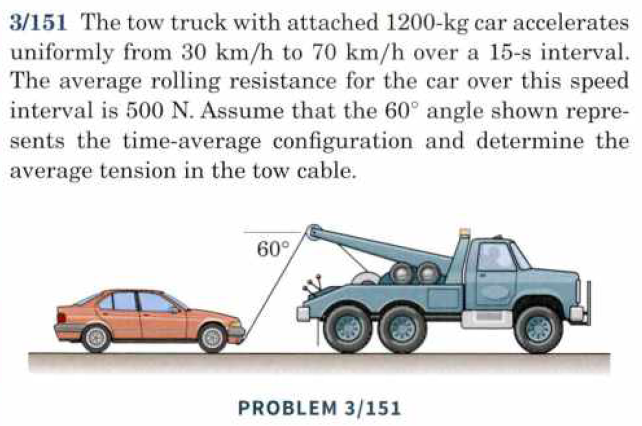

clear

g = 9.81;

% Rumskib data
m = 1200; 
v1 = 30/3.6;
v2 = 70/3.6;
theta = deg2rad(60)

theta =        1.0472



t1 = 0; t2 = 15;

Frul = -500;


% Integralet for ændring i kraft i x-retning
syms T

eq = m*v1 + (Frul + T*cos(theta))*t2 == m*v2;

T = vpa(solve(eq, T),4)

$$T = 2778.0$$

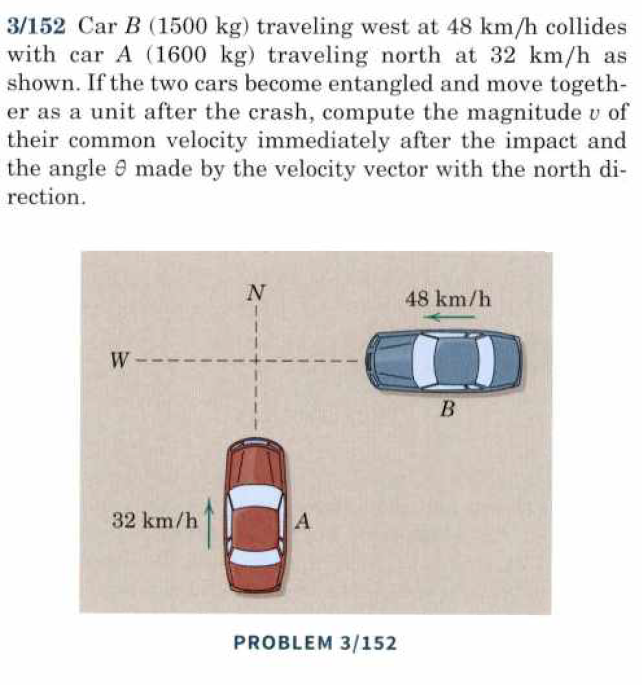

clear

% bil B
mb = 1500;
vb = 48

vb =     48



Pb = mb*vb

Pb =        72000




% bil A
ma = 1600;
va = 32

va =     32



Pa = ma*va

Pa =        51200



m_tot = mb + ma;

% impuls i x og y
syms vx vy
Fx = Pb == m_tot*vx;
Fy = Pa == m_tot*vy;

vx = vpa(solve(Fx, vx),3)

$$vx = 23.2$$

vy = vpa(solve(Fy, vy),3)

$$vy = 16.5$$


v_efter = sqrt(vx^2 + vy^2);
v_efter = vpa(v_efter, 4)

$$v\_efter = 28.5$$


theta = atan(Pb/Pa)

theta =       0.95265


rad2deg(theta)

ans =        54.583


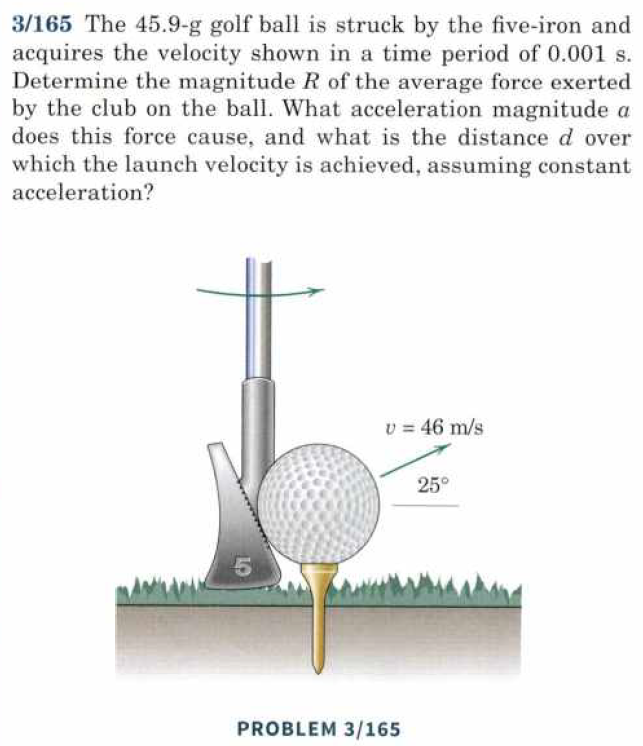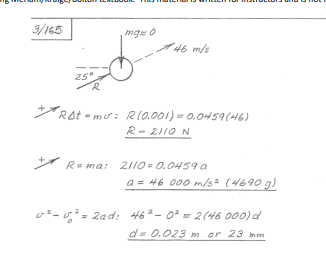

clear



